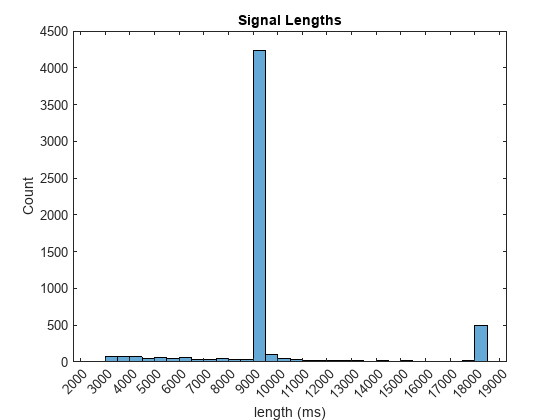

if ~isfile('PhysionetData.mat')
    ReadPhysionetData         
end
load PhysionetData

L = cellfun(@length,Signals);
h = histogram(L);
xticks(0:1000:20000);
xticklabels(0:1000:20000);
title('Signal Lengths')
xlabel('length (ms)')
ylabel('Count')

% most data has lengthof 9000 ms
% train model using only the ECGs with length of 9000 ms, delete the others 
[signals_9000, labels_9000] = segmentSignals(Signals, Labels);

summary(labels_9000) % how many signals of each group

     A       718 
     N      4937 



fs = 300; % frequency of ECGs (Hz)

arrX = signals_9000(labels_9000 =='A');
arrY = labels_9000(labels_9000 =='A');

normX = signals_9000(labels_9000 =='N');
normY = labels_9000(labels_9000 =='N');

% used number of arrythmic signals (limits number of signals)
[trainIndexArr,~,testIndexArr] = dividerand(718,0.85,0.0,0.15); % divides signals into training and testing groups (85% training, 15% testing)
[trainIndNorm,~,testIndNorm] = dividerand(718,0.85,0.0,0.15);

XTrainArr = arrX(trainIndexArr); % creates arrythmic (uses the signals) group to TRAIN program
YTrainArr = arrY(trainIndexArr); % creates arrythmic (uses the labels) group to TRAIN program

XTrainNorm = normX(trainIndNorm); % creates normal (uses the signals) group to TRAIN program
YTrainNorm = normY(trainIndNorm); % creates normal (uses the labels) group to TRAIN program

XTestArr = arrX(testIndexArr); % creates arrythmic (uses the signals) group to TEST program
YTestArr = arrY(testIndexArr); % creates arrythmic (uses the labels) group to TEST program

XTestNorm = normX(testIndNorm); % creates normal (uses the signals) group to TEST program
YTestNorm = normY(testIndNorm); % creates normal (uses the labels) group to TEST program

signals_85percent = floor(718 * 0.85)

signals_85percent = 610

signals_15percent = floor(718 * 0.15)

signals_15percent = 107


XTrain = [repmat(XTrainArr(1:signals_85percent),7,1); XTrainNorm(1:signals_85percent)]; % creates group of ALL training signals
YTrain = [repmat(YTrainArr(1:signals_85percent),7,1); YTrainNorm(1:signals_85percent)]; % creates group of ALL training labels

XTest = [repmat(XTestArr(1:signals_15percent),7,1); XTestNorm(1:signals_15percent)]; % creates group of ALL testing signals
YTest = [repmat(YTestArr(1:signals_15percent),7,1); YTestNorm(1:signals_15percent);]; % creates group of ALL training labels


layers = [ ...
    sequenceInputLayer(1)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex


options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 150, ...
    'InitialLearnRate', 0.01, ...
    'SequenceLength', 1000, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);

net = trainNetwork(XTrain,YTrain,layers,options);